# Correção Teste #1

#### Exercício 1

**a) **0.1000 e 0.1001, por exemplo

**b)**

NumerosDeMaquina=(9*10^3)*5*2+1

NumerosDeMaquina = 90001

NumerosMaiores50=(4*10^3)-1

NumerosMaiores50 = 3999

**c)**

b=10;t=4;m=-2;M=2;
Omega=(1-b^-t)*b^M

Omega = 99.9900

omega=b^(m-1)

omega = 1.0000e-03

epsilon=b^(1-t)

epsilon = 1.0000e-03

**d)**

x=5.038;y=43.58;
x+y

ans = 48.6180

fl(x+y)= 48.62

y*y  % fl(y*y)=1899

ans = 1.8992e+03

1899+x % fl(x+y^2)=1904

ans = 1.9040e+03

1904/3 % fl((x+y^2)/3)=634.7

ans = 634.6667

#### Exercício 2

f=@(x,h) (sin(x+h)-sin(x))./h;

**a)**

g=@(x,h) 2*(cos(x+h/2).*sin(h/2))./h;

**b)**

h=10.^(0:-1:-20);
format long
[f(1.2,h)',g(1.2,h)']

ans =   -0.123542682147636  -0.123542682147636
   0.315190994499667   0.315190994499666
   0.357691558615958   0.357691558615959
   0.361891674579562   0.361891674579569
   0.362311151919092   0.362311151918484
   0.362353094285339   0.362353094275204
   0.362357288508086   0.362357288457070
   0.362357708283412   0.362357707874719
   0.362357754912779   0.362357749816478
   0.362357810423930   0.362357754010654
   0.362357921446232   0.362357754430072
   0.362365693007405   0.362357754472013
   0.362487817540114   0.362357754476208
   0.361932706027801   0.362357754476627
   0.366373598126302   0.362357754476669


**c) **cancelamento subtrativo

**d) **Como $f'(x)=\lim_{x\to 0} \frac{f(x+h)-f(x)}{h}$, sugere-se o uso da função g(x,h) para aproximar a derivada da função sen(x) (=cos(x))

cos(1.2)

ans =    0.362357754476674


g(1.2,h(end))

ans =    0.362357754476674


#### Exercício 3

**a) **

x=0:0.1:0.5;
y=[1.0000 1.0095 1.0365 1.0787 1.1346 1.2027]; 
pval2=polDifDiv(x(3:5),y(3:5),0.25) % polinómio de grau 1; pontos interpolação: 0.2,0.3,0.4

pval2 =    1.055887500000000


pval3=polDifDiv(x(2:5),y(2:5),0.25) % polinómio de grau 2; pontos interpolação: 0.1,0.2,0.3,0.4

pval3 =    1.055793750000000


pval4=polDifDiv(x(1:5),y(1:5),0.25) % polinómio de grau 3; pontos interpolação: 0.1,0.2,0.3,0.4,0.5

pval4 =    1.055812500000000


**b)**

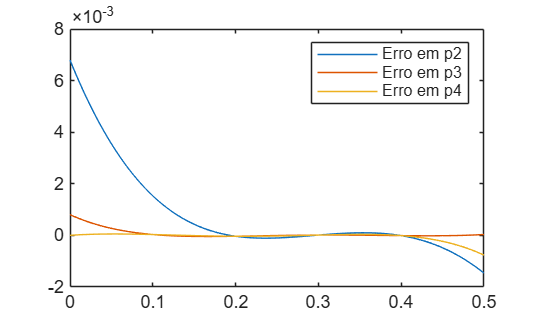

f=@(t) 1+t.*log(1+t);
t=linspace(0,0.5);
p2=polDifDiv(x(3:5),y(3:5),t);
p3=polDifDiv(x(2:5),y(2:5),t);
p4=polDifDiv(x(1:5),y(1:5),t);
plot(t,f(t)-p2,t,f(t)-p3,t,f(t)-p4)
legend('Erro em p2','Erro em p3','Erro em p4')

ou

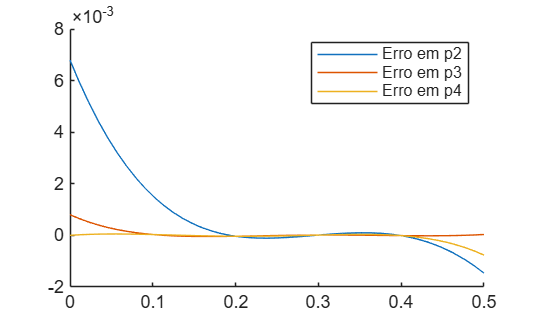

erro2=@(t)f(t)-polDifDiv(x(3:5),y(3:5),t);
erro3=@(t)f(t)-polDifDiv(x(2:5),y(2:5),t);
erro4=@(t)f(t)-polDifDiv(x(1:5),y(1:5),t);
clf
hold on
fplot(erro2,[0,0.5])
fplot(erro3,[0,0.5])
fplot(erro4,[0,0.5])
legend('Erro em p2','Erro em p3','Erro em p4')
hold off

#### Exercício 4

Não faz parte do programa

#### Exercício 5

**a) **e** b)**

f=@(x) 2./(1+x.^2);
disp('      N         Trap          erroT    racio')

      N         Trap          erroT    racio


k=1;erro(1)=0;
for N=2.^(1:7)
    integral=regTrapezio(f,-1,1,N);
    k=k+1;
    erro(k)=abs(pi-integral);
    fprintf('    %3i  %16.12f   %8.3e %6.2f \n',N,integral,erro(k),erro(k-1)/erro(k))
end

      2    3.000000000000   1.416e-01   0.00 
      4    3.100000000000   4.159e-02   3.40 
      8    3.131176470588   1.042e-02   3.99 
     16    3.138988494491   2.604e-03   4.00 
     32    3.140941612041   6.510e-04   4.00 
     64    3.141429893175   1.628e-04   4.00 
    128    3.141551963486   4.069e-05   4.00 


table(N,integral,)

Erro da ordem de $h^2$ (rácio ->2^2)

**c) **erro$ \le \frac2{180}\left(\frac2{N}\right)^4\times48\le0.5e-7$

auxN=2/(90/48*0.5*10^-7)^(1/4)

auxN = 114.2976

N=116; % Escolher o primeiro par maior que auxN
abs(regSimpson(f,-1,1,N)-pi) % A aproximação é bastante melhor do que imposto

ans = 1.0423e-12